%zadanie 1
X0 = 0.123456789; %wartosc poczatkowa
z = 9 %parametr liczby "zębów piły

z = 9

Xn=X0;
N = 10000000 %Ilość iteracji

N = 10000000

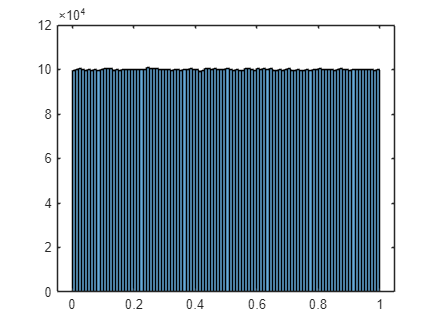

A = zeros(1,N);
B = A;
for i = 1:N
    A(i) = Xn;
    Xn1 = Xn*z-floor(Xn*z);
    Xn = Xn1;
end
figure(1);
edges = 100;
H = histogram(A,edges);

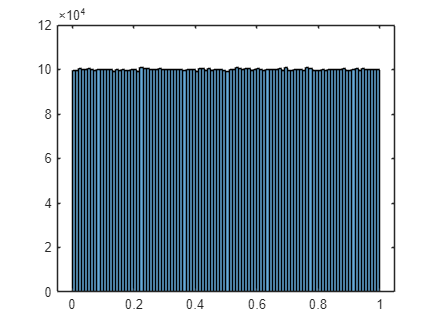


%zadanie 2
% Parametry generatora (dostosowane do liczb w zakresie [0, m-1])
a0 = 1664525; 
a1 = 1013904223;
c = 12345; 
m = 2^32;

% Inicjalizacja wartości początkowych
Xn = floor(X0 * m); % Przekształcenie X0 do skali [0, m-1]
Xn1 = floor(0.4353453 * m); % Podobnie dla Xn1


% Inicjalizacja wartości początkowych
Xn = X0; 
Xn1 = 0.4353453; % dowolna wartość początkowa dla X_{n-1}

for i = 1:N
    B(i) = Xn / m; % Normalizacja do [0,1] przy zapisie do tablicy
    Xn2 = mod(a0 * Xn + a1 * Xn1 + c, m); % Obliczenie nowej wartości
    Xn1 = Xn; % Przesunięcie wartości
    Xn = Xn2; % Aktualizacja Xn
end

% Histogram wyników
figure(2);
histogram(B, edges);